# Stock Data - Distribution Testing

In this exercise, you will compare four distribution fits made to stock returns for Magnum Hunter Resources Corporation stock (MHR) with the empirical data both visually, and formally using hypothesis testing.

## 1.

Run the script `stockDataDistributionFitting.m`from the exercise *Stock Data – Distribution Fitting*. This script creates four distribution fits that are stored in the cell array `retFits`.

MHRret =          0
   -0.0328
    0.0328
   -0.0245
    0.0082
   -0.0165
   -0.0426
         0
   -0.1298
    0.0099


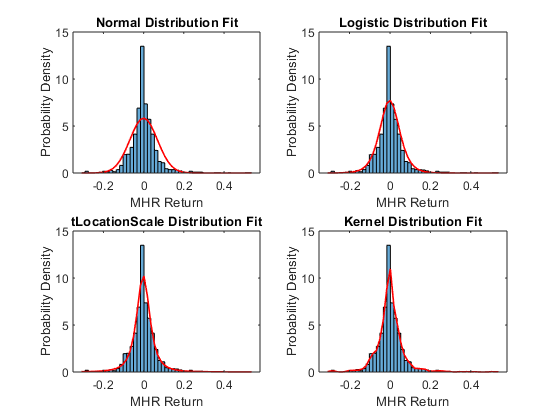

stockDataDistributionFitting

## 2. 

Calculate the Empirical Cumulative Density Function (`ecdf`) of the MHR returns. For each distribution stored in `retFits,` calculate the Cumulative Density Function (`cdf`),  and plot this onto a separate subplot along with the ECDF for the MHR returns. **Hint: **You will need to return the second output from `ecdf` to obtain the stock returns at which the ECDF is evaluated.

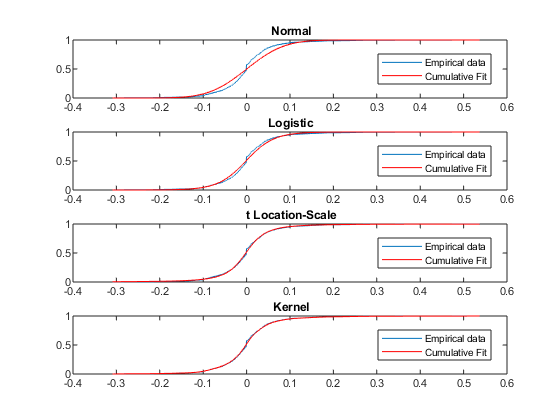

[retECDF, MHRsampled] = ecdf(MHRret);

% Plot the CDF for each distribution fit and compare with ECDF:
figure
for k = 1:length(retFits)
    retCDF = cdf(retFits{k},MHRsampled);
    subplot(4,1,k)
    plot(MHRsampled,retECDF)
    hold on
    plot(MHRsampled,retCDF,'r')
    legend('Empirical data','Cumulative Fit', 'Location', 'best')
    title(['\bf ' retFits{k}.DistributionName])
end

## 3.

For each distribution, generate a population of 10000 random numbers using the `random`function. Use `kstest2`to determine whether the random numbers generated come from the same population as the MHR returns. 

for k = 1:length(retFits)
    retDistRandom = random(retFits{k},1e4,1);
    % Compare the random numbers with the original data:
    [h,p] = kstest2(retDistRandom,MHRret);
    if (h == 0)
        disp(['For Distribution: ' retFits{k}.DistributionName ' h0 is accepted with p = ' num2str(p)]) 
    else
        disp(['For Distribution: ' retFits{k}.DistributionName ' h0 is rejected with p = ' num2str(p)])
    end
end

For Distribution: Normal h0 is rejected with p = 4.2561e-12
For Distribution: Logistic h0 is rejected with p = 7.6305e-05
For Distribution: t Location-Scale h0 is rejected with p = 0.0013297
For Distribution: Kernel h0 is rejected with p = 0.00044942



% All distributions are rejected!